# Calling TTB-2D Software

No redux model is used! Are sure about this?
Building model system matrices ... DONE


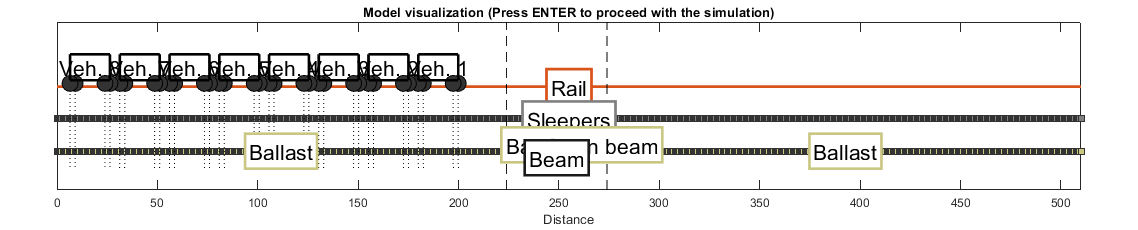

The figure "Model visualization" shows the model to simulate.
Performing Dynamic Calculations (Coupled System) ...
Time step 132 of 10953 (1.21%)
Time step 299 of 10953 (2.73%)
Time step 461 of 10953 (4.21%)
Time step 618 of 10953 (5.64%)
Time step 775 of 10953 (7.08%)
Time step 931 of 10953 (8.5%)
Time step 1083 of 10953 (9.89%)
Time step 1243 of 10953 (11.35%)
Time step 1392 of 10953 (12.71%)
Time step 1542 of 10953 (14.08%)
Time step 1682 of 10953 (15.36%)
Time step 1833 of 10953 (16.74%)
Time step 1987 of 10953 (18.14%)
Time step 2142 of 10953 (19.56%)
Time step 2291 of 10953 (20.92%)
Time step 2438 of 10953 (22.26%)
Time step 2580 of 10953 (23.56%)
Time step 2724 of 10953 (24.87%)
Time step 2864 of 10953 (26.15%)
Time step 3001 of 10953 (27.4%)
Time step 3144 of 10953 (28.7%)
Time step 3264 of 10953 (29.8%)
Time step 3314 of 10953 (30.26%)
Time step 3363 of 10953 (30.7%)
Time step 3415 of 10953 (31.18%)
Time step 3467 of 10953 (31.65%)
Time step 3520 of 10953 (32.14%)
Time step 35

% Main script to run TTB-2D model

% *************************************************************************
% *** Script part of TTB-2D tool for Matlab environment.                ***
% *** Licensed under the GNU General Public License v3.0                ***
% *** Author: Daniel Cantero (daniel.cantero@ntnu.no)                   ***
% *** For help, modifications, and collaboration contact the author.    ***
% *************************************************************************

clear; clc;

% --------------------------- Definitions ---------------------------------


% ---- Train ----
% Definitions for Train

% Not a function.
% Defines the content of the variable Train.

% *************************************************************************
% *** Script part of TTB-2D tool for Matlab environment.                ***
% *** Licensed under the GNU General Public License v3.0                ***
% *** Author: Daniel Cantero (daniel.cantero@ntnu.no)                   ***
% *** For help, modifications, and collaboration contact the author.    ***
% *************************************************************************

% Velocity
Train.vel = 100/3.6;          % Train velocity [m/s]

% -- Mechanical properties --

% File loading path
Train.Load.path = '';

% Defnintion of successive vehicles
% veh_num = 1; run([Train.Load.path,'TrainProp_Manchester_BenchMark']);

% Optional: To add more successive vehicles to the train model, define
%   each additional vehicle/wagon as follows. Simply define the correct
%   vehicle number and call the desired vehicle properties
% Example (uncomment to use)
% veh_num = 2; run([Train.Load.path,'TrainProp_Manchester_Benchmark']);
% veh_num = 3; run([Train.Load.path,'TrainProp_Manchester_Benchmark']);

% Additional vehicle/wagon properties included in TTB-2D are:

% % AVE S103 ICE3 configuration with 8 coaches
veh_num = 1; run([Train.Load.path,'TrainProp_AVE_S103_ICE3_Velaro_E_C1']);
veh_num = 2; run([Train.Load.path,'TrainProp_AVE_S103_ICE3_Velaro_E_C2367']);
veh_num = 3; run([Train.Load.path,'TrainProp_AVE_S103_ICE3_Velaro_E_C2367']);
veh_num = 4; run([Train.Load.path,'TrainProp_AVE_S103_ICE3_Velaro_E_C45']);
veh_num = 5; run([Train.Load.path,'TrainProp_AVE_S103_ICE3_Velaro_E_C45']);
veh_num = 6; run([Train.Load.path,'TrainProp_AVE_S103_ICE3_Velaro_E_C2367']);
veh_num = 7; run([Train.Load.path,'TrainProp_AVE_S103_ICE3_Velaro_E_C2367']);
veh_num = 8; run([Train.Load.path,'TrainProp_AVE_S103_ICE3_Velaro_E_C8']);

% % Eurostar configuration
% veh_num = 1; run([Train.Load.path,'TrainProp_Eurostar_Locomotive']);
% veh_num = 2; run([Train.Load.path,'TrainProp_Eurostar_EC1']);
% veh_num = 3; run([Train.Load.path,'TrainProp_Eurostar_EC2_EC8']);
% veh_num = 4; run([Train.Load.path,'TrainProp_Eurostar_EC2_EC8']);
% veh_num = 5; run([Train.Load.path,'TrainProp_Eurostar_EC2_EC8']);
% veh_num = 6; run([Train.Load.path,'TrainProp_Eurostar_EC2_EC8']);
% veh_num = 7; run([Train.Load.path,'TrainProp_Eurostar_EC2_EC8']);
% veh_num = 8; run([Train.Load.path,'TrainProp_Eurostar_EC2_EC8']);
% veh_num = 9; run([Train.Load.path,'TrainProp_Eurostar_EC2_EC8']);
% veh_num = 10; run([Train.Load.path,'TrainProp_Eurostar_EC9']);
% veh_num = 11; run([Train.Load.path,'TrainProp_Eurostar_Locomotive']);

% % Chinese Star (Exmaple: Locomotive + 3 wagons)
% veh_num = 1; run([Train.Load.path,'TrainProp_ChineseStarPowerCar']);
% veh_num = 2; run([Train.Load.path,'TrainProp_DoubleDeckPassengerCoach']);
% veh_num = 3; run([Train.Load.path,'TrainProp_DoubleDeckPassengerCoach']);
% veh_num = 4; run([Train.Load.path,'TrainProp_DoubleDeckPassengerCoach']);

% % Pioneer M vehicle
% veh_num = 1; run([Train.Load.path,'TrainProp_Pioneer_M_vehicle']);

% % Pioneer R vehicle
% veh_num = 1; run([Train.Load.path,'TrainProp_Pioneer_R_vehicle']);

% % Shinkansen S300
% veh_num = 1; run([Train.Load.path,'TrainProp_ShinkansenS300']);

% Copy of Train.vel
Train.Veh(1).vel = Train.vel;

clear veh_num

% ---- End of script ----


% ---- Track ----
A02_Track;

% ---- Bridge ----
A03_Bridge;


% ---- Options ----
A04_Options;

% --------------------------- Calculations --------------------------------

B00_Calculations;


%% -------------------- Results processing and plotting --------------------

% Model deformation plot at a given instant in time
% C01_ModelDeformationPlot(Calc,Model,Sol,Train);

% % Time history plot of user selected model point
% C02_TimeHistoryPlot(Model,Sol,Beam,Calc);

% Other user-specified plots of the results
% C03_TTB_2D_Plots;

% ---- End of script ----

### Assumptions: 

#### (Change these to tune results accordingly)

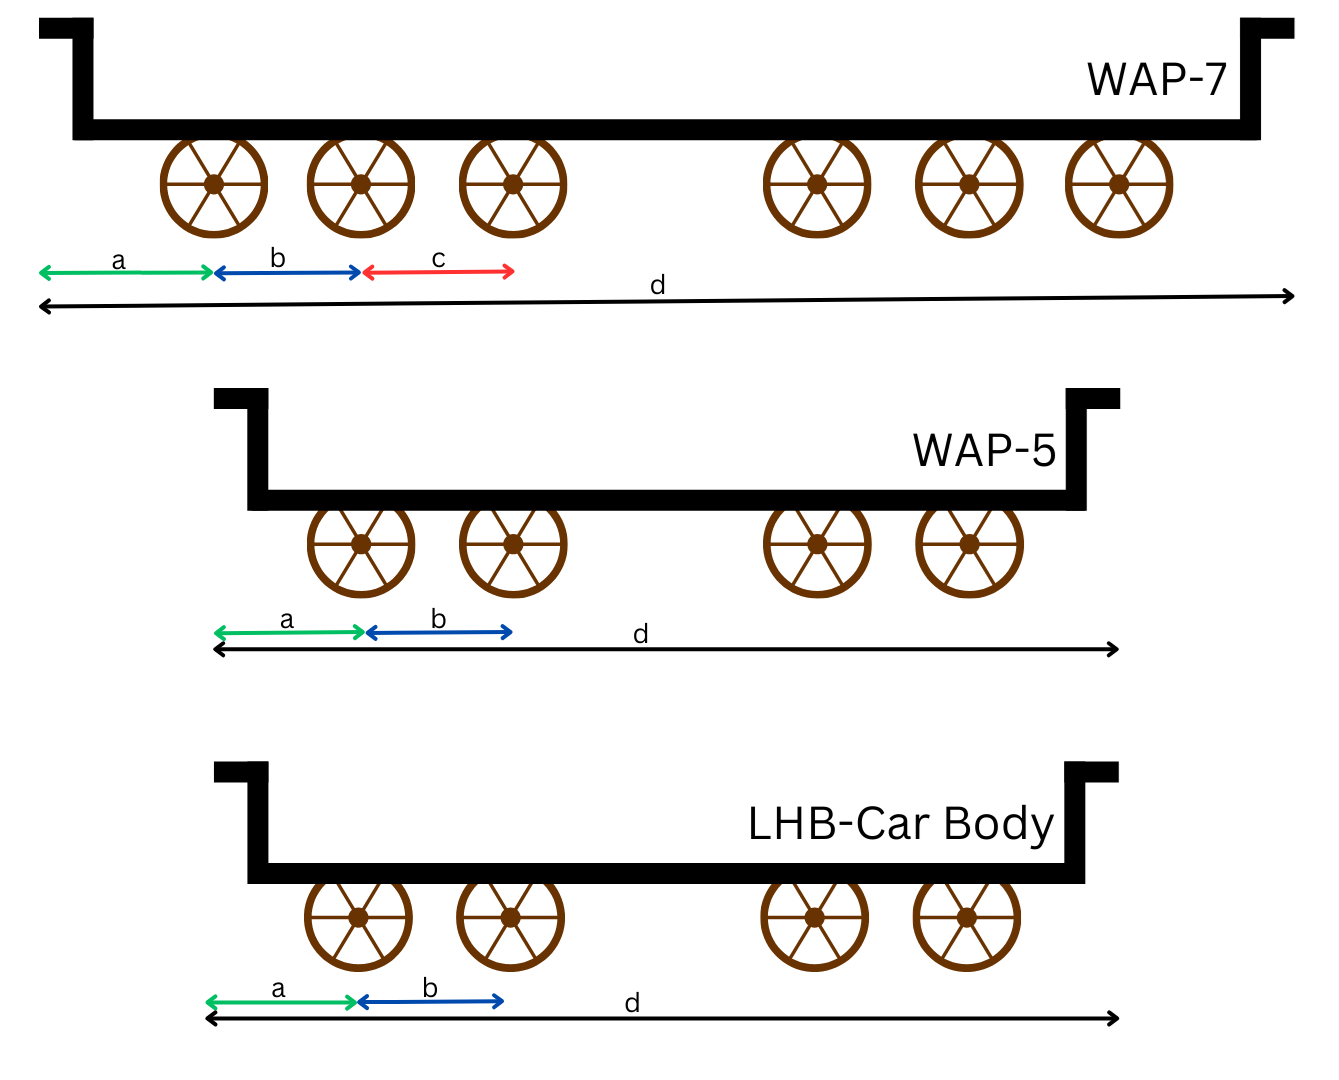

% mm to m dimensions
coco_a = 2431/1000;
coco_b = 1850/1000;
coco_c = 1850/1000;
coco_d = 20562/1000; % Loco Outline drawing for 25kv ac locomotive class wap7

bobo_a = 2531/1000;
bobo_b = 2800/1000;
bobo_d = 18162/1000;

veh_num = 1;
car_a = Train.Veh(veh_num).Body.Le(1);
car_b = Train.Veh(veh_num).Bogie.L(1);
car_d = Train.Veh(veh_num).Body.L+car_b+2*(car_a);
% Train.Veh(veh_num).Bogie.L = [1,1]*2.5;                   % Bogies length [m] (From wheel to wheel)
% Train.Veh(veh_num).Body.L = 17.375;                       % Main body length [m] (From bogie to bogie)
% Train.Veh(veh_num).Body.Le = [1,1]*(7.4/2);               % Additional distance [m], front and back

% % Specify the file path
% file_path = 'ttb_120.csv';
% 
% % Read the numeric data from the CSV file
% numeric_data = csvread(file_path); % or readmatrix(file_path);
sp_or = Train.vel;
% Display the data
% numeric_data
k_continue = 1;
t_per = 50;
t_per_add = 0;
data2plot = 1;
% Selection of time-step to plot
t_per = t_per + t_per_add;
Data = Sol.Model.Nodal.A;
% Checking selected time-step
if t_per < 0
    t_per = 0;
elseif t_per > 100
    t_per = 100;
end % if t_per < 0
t = round(Calc.Solver.num_t*t_per/100)+1-ceil(t_per/100);
x = linspace(1,round(500/sp_or),length( Model.Mesh.XLoc.rail_vert));
y = Data(Model.Mesh.DOF.rail_vert,t);

ans = 1701

ans = 1701

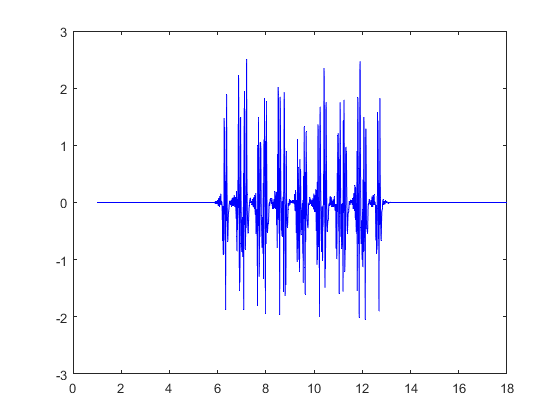


plot(x,y)

time_sec = x;
acceleration_g = y;

% Given points
x1 = [60/3.6 80/3.6 120/3.6];
y1 = [0.17 0.29 0.36];
p = polyfit(x1,y1,length(y1)-1);
thee = polyval(p,sp_or);

# Analysis of the Train Data

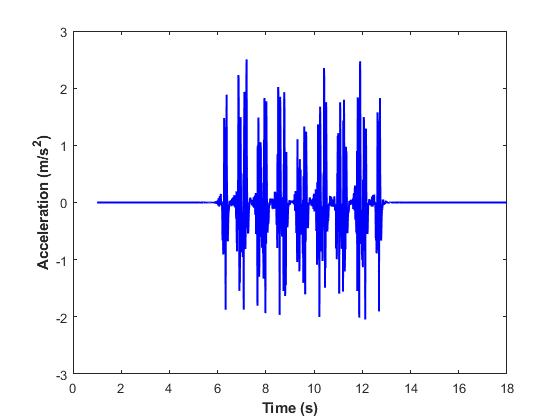

t = time_sec;
x = acceleration_g;
plot(t,x,'b','LineWidth',1.5)
xlabel('Time (s)','FontWeight',"bold");
ylabel('Acceleration (m/s^{2})','FontWeight',"bold");

% Load Distribution
degree = 1;  % Degree 1 for a linear regression (a straight line)
coefficients = polyfit(t(1:round(length(x)/2)), x(1:round(length(x)/2)), degree);
s1 = coefficients(1);  % The slope is the first coefficient
coefficients = polyfit(t(round(length(x)/2):end), x(round(length(x)/2):end), degree);
s2 = coefficients(1);  % The slope is the first coefficient

% 1->Flat, 2->Linear Increasing, 3->Linear Decreasing,
% 4->Anti-Streamlined, 5->Random

if s1<0 && s2>0
    found_dist = 4;
elseif s1 <0 && s2<0
    found_dist = 3;
elseif s1 >0 && s2>0
    found_dist = 2;
else
    found_dist = 1;
end

#### Counting Axles

for i = 1:1
    windowSize = 3;
    b = (1/windowSize)*ones(1,windowSize);
    a = 1;
    
    x = filter(b,a,x);
end
x(x<0) = -0.1; % Adding a compensator constant for averaged out amplitude

plot(t,x,'b','LineWidth',1.5)
xlabel('Time (s)','FontWeight',"bold");
ylabel('Acceleration (m/s^{2})','FontWeight',"bold");

%% Second yield
A=x;
maxarr = islocalmax(A);
A=x;
minarr = islocalmin(A);

y2=x;
hold on;
ind = 0;  %0= sleep, 1=look
look=-1;
threshold = thee;  %________________________________Change for new data
i = 1;

% Timestamps
tim = [];
red_peaks=[];

Axles_Passed = 0;
while i<length(y2)
    if ind==0 && minarr(i)==1
        ind  = 1;
        look = i;
    end
    if (ind==1 && maxarr(i)==1 && y2(i)-y2(look)>=threshold) ||(ind==1 && maxarr(i)==1 && y2(i)>1.5 && train_velocity>70)
        plot(t(i),y2(i),'r*','LineWidth',4);
        tim = [tim,t(i)];
        red_peaks=[red_peaks,y2(i)];
        ind = 0;
        Axles_Passed = Axles_Passed + 1;
    elseif ind==1 && minarr(i)==1 
        look=i;
    end
    i = i+1;
end



disp(['Number of Axles Passed: ' num2str(Axles_Passed)]);

Number of Axles Passed: 32


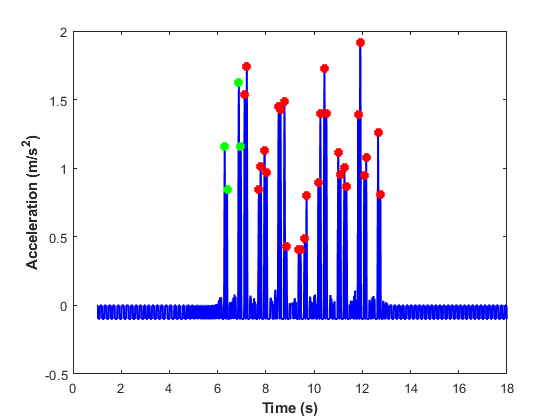


%No. of Coaches, Loco Type, Train Length:
small_len = (tim(2)-tim(1)+tim(3)-tim(2)+tim(5)-tim(4)+tim(6)-tim(4))/4;
large_len = tim(4)-tim(3);
lt = 0;
train_len = 0;
if large_len > 3*small_len
    lt = 7;
    train_len = train_len+coco_d;
else
    lt = 5;
    train_len = train_len+bobo_d;
end
found_loco_type = lt;

found_coaches = (Axles_Passed-found_loco_type+1)/4;

train_len = train_len + (car_d*found_coaches);
for i = 1:found_loco_type-1
    plot(tim(i),red_peaks(i),'g*','LineWidth',4)
end
hold off;

Net Track Deflection

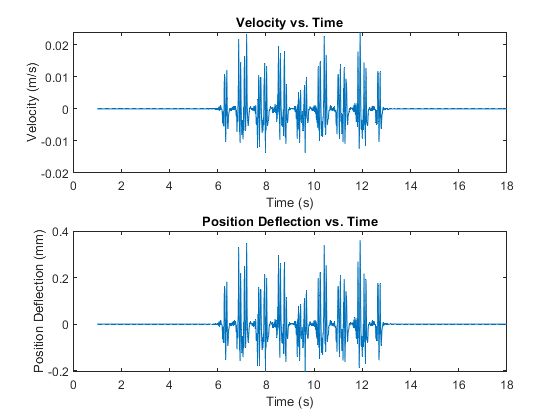

% Sample acceleration and time data (replace with your actual data)
acc = acceleration_g; % Acceleration in m/s^2
ti = time_sec; % Time in seconds

% Initialize variables for velocity and position
vel = zeros(size(acc));
position = zeros(size(acc));

% Position Deflection Calculation
for i = 2:length(acc)
    delta_t = ti(i) - ti(i-1);
    average_acceleration = (acc(i) + acc(i-1)) / 2;
    
    % Calculate the change in velocity
    delta_v = average_acceleration * delta_t;
    
    % Update velocity and position
    vel(i) = delta_v;
    position(i) = vel(i) * delta_t + 0.5 * delta_v * delta_t;
end
position = position * 1000; % Converting m to mm
net_diflection = max(position);
% Plot velocity and position deflection over time
figure;
subplot(2,1,1);
plot(ti, vel);
xlabel('Time (s)');
ylabel('Velocity (m/s)');
title('Velocity vs. Time');

subplot(2,1,2);
plot(ti, position);
xlabel('Time (s)');
ylabel('Position Deflection (mm)');
title('Position Deflection vs. Time');

figure;

### Counting Flat Wheels

datas = red_peaks;

% Define the threshold for a spike
thresholdss = 0.4;

% Fit a linear trend to your data
p = polyfit(1:length(datas), datas, 1);

% Subtract the linear trend
datas = datas - polyval(p, 1:length(datas));

% Find peaks above the threshold
[pks, locs] = findpeaks(datas, 'MinPeakHeight', thresholdss);

% Number of spikes
num_spikes = length(pks);

% Display the results
fprintf('Number of spikes: %d\n', num_spikes);

Number of spikes: 4


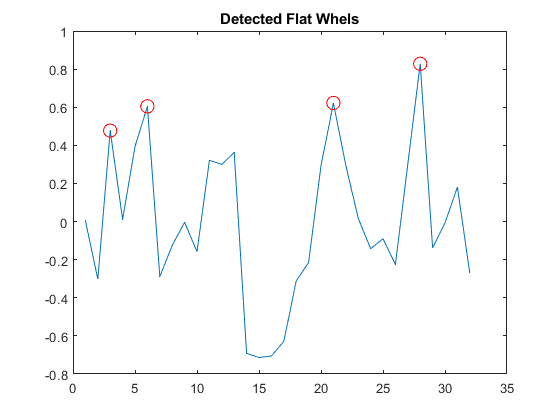

% Plot the graph with detected spikes
figure;
plot(datas);
hold on;
plot(locs, pks, 'ro', 'MarkerSize', 10);
title('Detected Flat Whels');
hold off;

### Speed of the Train:

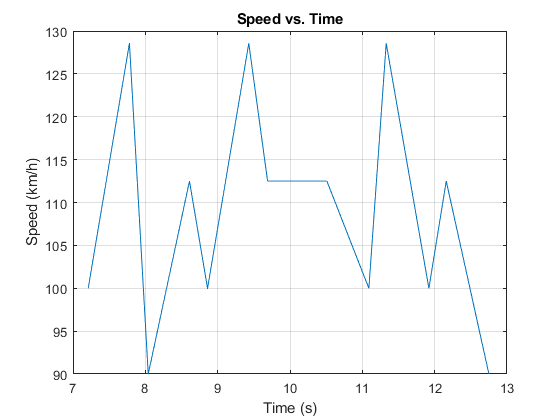

distance = car_b;
dist_bet = car_d-car_b-car_a;
tim = tim(found_loco_type:end);

if round(length(tim)/2)-length(tim)/2 ~=0
    tim = [tim tim(end)+tim(end)-tim(end-1)];
end
velocities = distance./(tim(2:2:end) - tim(1:2:end));
timpts = tim(2:2:end);

kmph_vel = velocities*3600/1000;
plot(timpts,kmph_vel)
xlabel('Time (s)');
ylabel('Speed (km/h)');
title('Speed vs. Time');
grid on;


avgvel = mean(kmph_vel);
disp(['Speed of the Train (km/h): ' num2str(avgvel)]);

Speed of the Train (km/h): 109.1582


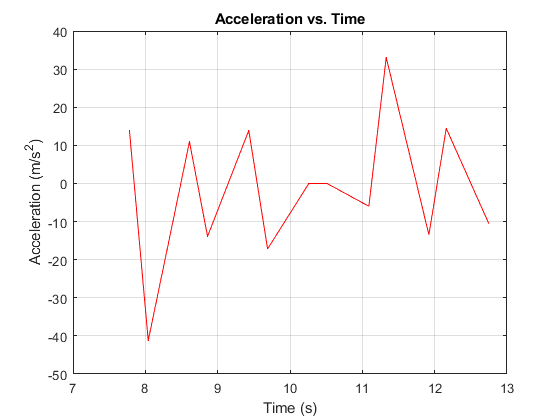

% Example data (replace these with your actual velocity and time data)
velocity = velocities;  % Array of velocities
time = timpts ;        % Array of corresponding time stamps

% Calculate the change in velocity and change in time
delta_v = diff(velocity);  % Compute the difference between consecutive velocities
delta_t = diff(time);      % Compute the difference between consecutive time stamps

% Calculate acceleration
acceleration = delta_v ./ delta_t;

% Plot acceleration over time (optional)
plot(time(2:end), acceleration,'r');
xlabel('Time (s)');
ylabel('Acceleration (m/s^{2})');
title('Acceleration vs. Time');
grid on;


% Display acceleration values
disp(['Acceleration(m/s^2): ' num2str(acceleration)]);

Acceleration(m/s^2): 13.9237     -41.2088      10.9649     -13.8889      13.9237     -17.1703            0            0     -5.98659      33.0688     -13.4517      14.4676     -10.5932




% Train Type
found_tt = 0;
if net_diflection>1
    found_tt = 1;
end

## Displaying the Result:

Train_Specs = {'No. of Coaches'; 'Loco Type'; 'Approx Velocity (kmph)'; 'Flat Wheels'; 'Train Length (m)';'Net Track Deflection (mm)'; 'Type (0-Passenger, 1-Freight)'; 'Load Distribution'};
Output = [found_coaches;  found_loco_type;    avgvel;               num_spikes;          train_len;        net_diflection;             found_tt;                         found_dist];
% Create a table
T = table(Train_Specs,Output);
% Display the table in tabular form
disp(T);

               Train_Specs               Output 
    _________________________________    _______

    {'No. of Coaches'               }          7
    {'Loco Type'                    }          5
    {'Approx Velocity (kmph)'       }     109.16
    {'Flat Wheels'                  }          4
    {'Train Length (m)'             }     223.93
    {'Net Track Deflection (mm)'    }    0.36017
    {'Type (0-Passenger, 1-Freight)'}          0
    {'Load Distribution'            }          4

